clc
clear

1) Find the number of states, inputs, and outputs for `G1` and `G2`.

load('Ex4-data');
fprintf('G1:')

G1:

fprintf('number of states = %1.0f', size(get(G1, 'A'), 1));

number of states = 4

fprintf('number of inputs = %1.0f', size(get(G1, 'B'), 2));

number of inputs = 1

fprintf('number of outputs = %1.0f', size(get(G1, 'C'), 1));

number of outputs = 1


fprintf('G2:')

G2:

fprintf('number of states = %1.0f', size(get(G2, 'A'), 1));

number of states = 4

fprintf('number of inputs = %1.0f', size(get(G2, 'B'), 2));

number of inputs = 1

fprintf('number of outputs = %1.0f', size(get(G2, 'C'), 1));

number of outputs = 1

2) Calculate eigenvalues of `G1` and `G2` in Matlab. Are `G1` and `G2` stable? Categorize the eigenvalues as being fast or slow. 

*Answer: All eigenvalues of both systems lie inside the unit circle. Hence, both systems are stable. Eigenvalues with a small norm are fast and eigenvalues with norm close to 1 are slow. For *`G1`*, 0.98 is slow and the rest are fast. For *`G2`*, 0.90 and 0.85 as slow eigenvalues and -0.1 and 0.3 are fast.  *

eigenvalues1 = eig(G1)

eigenvalues1 =     0.9800
    0.4000
    0.2000
    0.1500


if all(abs(eigenvalues1)<1)
    fprintf(['G1 is a discrete-time system with all eigenvalues ' ...
             'inside the unit circle, hence, is stable.'])
end

G1 is a discrete-time system with all eigenvalues inside the unit circle, hence, is stable.


eigenvalues2 = eig(G2)

eigenvalues2 =    -0.1000
    0.3000
    0.8500
    0.9000


if all(abs(eigenvalues2)<1)
    fprintf(['G2 is a discrete-time system with all eigenvalues ' ...
             'inside the unit circle, hence, is stable.'])
end

G2 is a discrete-time system with all eigenvalues inside the unit circle, hence, is stable.

3) Compare the impulse response of the full and reduced order models, `G1` and `G1DP`. 

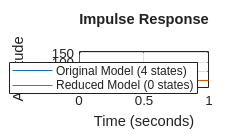

% Reduce LTI model order using mode selection
 
% Select modes between lower and upper cutoff frequencies
G1DP = freqsep(G1,4.464056301248626);
[~,G1DP] = freqsep(G1DP,0.001);

% Compare original and reduced model
figure
impulseplot(G1,G1DP);
legend(['Original Model (',num2str(order(G1)),' states)'],...
       ['Reduced Model (',num2str(order(G1DP)),' states)']);
grid on

*Answer: at the beginning, there is a large devaition between the impulse response of the two systems. As time passes, the modes corresponding to the faster eigenvalues goes to zero and the responses become more similar. *`G1DP`* approximates *`G1`* fairly well, except at the very beginning.  *

4) According to the theory, what is the eigenvalue of the first-order approximated system, `G1DP`? Find the eigenvalue of `G1DP `using Matlab and check if the result matches your expectation.

*Answer:it is the slowest eigenvalue, which is 0.98.*

fprintf('eigenvalue of the reduced-order system: %f', eig(G1DP))

eigenvalue of the reduced-order system: 

5) Compare the impulse response to *exercise 3*. First-order reduction approximates which system, `G1` or `G2`, better? Why?

*Answer: The first-order reduced model poorly approximates G2 and the impulse responses are not similar. This is because G2 has two slow eigenvalue, 0.90 and 0.85. By selecting only the slowest one, 0.9, the other slow mode is ignored which results in a deficient approximation. *

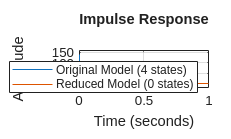

% Reduce LTI model order using mode selection
 
% Select modes between lower and upper cutoff frequencies
G2DP = freqsep(G2,10.80218620581149);
[~,G2DP] = freqsep(G2DP,0.001);

% Compare original and reduced model
figure
impulseplot(G2,G2DP);
legend(['Original Model (',num2str(order(G2)),' states)'],...
       ['Reduced Model (',num2str(order(G2DP)),' states)']);
grid on

6) Describe the effect of extending the frequency upper bound on the impulse response.

*Answer: The eigenvalues of *`G2` *are added one by one in the order of magnitude. The second-order reduction contains both slow modes of *`G2`* and significantly improves the approximation. As we continue to increase the order of the reduced system, the approximation becomes even more precise.*

 7) Check controllability and observability of `G1` and `G2`.

Co = ctrb(G1.A, G1.B);
if length(G1.A)-rank(Co) == 0
    fprintf('G1 is controllable.');
else
    fprintf('G1 is not controllable.');
end

G1 is controllable.


Ob = obsv(G1.A, G1.C);
if length(G1.A)-rank(Ob) == 0
    fprintf('G1 is observable.');
else
    fprintf('G1 is not observable.');
end

G1 is observable.


Co = ctrb(G2.A, G2.B);
if length(G2.A)-rank(Co) == 0
    fprintf('G2 is controllable.');
else
    fprintf('G2 is not controllable.');
end

G2 is controllable.


Ob = obsv(G2.A, G2.C);
if length(G2.A)-rank(Ob) == 0
    fprintf('G2 is observable.');
else
    fprintf('G2 is not observable.');
end

G2 is observable.

8) Set up balanced truncation according to Fig. 3. Pick `G1` as the full-order model and call the reduced

model `G1BT`. Start with setting `Reduced Order` to 1 and increase it gradually one at a time. Monitor

the error reduction in the impulse response.

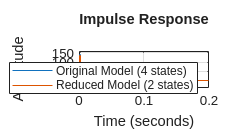

%% Reduce LTI model order using balanced truncation
 
% Compute reduced-order approximation
R2 = reducespec(G1,'balanced');
% Compute MOR data once
R2 = process(R2);
% Get reduced-order model
G1BT = getrom(R2,Order=2);
 
% Create comparison plot
f2 = figure();
h2 = impulseplot(f2,G1,G1BT);
legend(h2,['Original Model (',mat2str(order(G1)),' states)'],...
         ['Reduced Model (',mat2str(order(G1BT)),' states)']);
h2.AxesStyle.GridVisible = true;

 
 
% Remove temporary variables from Workspace
clear R2 f2 h2

9. Obtain a first-order reduced model of `G2` through balanced truncation and call it `G2BT`. Plot the

impulse responses of `G2BT` and compare it to `G2DP` obtained in question 5. Which method, dominant

pole approximation or balanced truncation, performs better? Why?

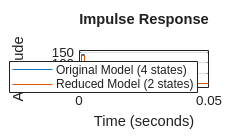

%% Reduce LTI model order using balanced truncation
 
% Compute reduced-order approximation
R = reducespec(G2,'balanced');
% Compute MOR data once
R = process(R);
% Get reduced-order model
G2BT = getrom(R,Order=2);
 
% Create comparison plot
f = figure();
h = impulseplot(f,G2,G2BT);
legend(h,['Original Model (',mat2str(order(G2)),' states)'],...
         ['Reduced Model (',mat2str(order(G2BT)),' states)']);
h.AxesStyle.GridVisible = true;

 
 
% Remove temporary variables from Workspace
clear R f h